# Practical Assignment 1: Accoustic localisation

Names:

NetIDs:

clear; clf; clc; close all;
addpath data
addpath functions

## 1. Calibration

load('calibration.mat')

### a) Measurement errors of each microphone at each sound pulse

The error at time step k for microphone j is given by:


$${\epsilon_{k,j} =\;y}_{k,j} -\frac{1}{8}\sum_{j=1}^8 y_{k,j}$$


% First get the means of all the TOA measurements
means = mean(y_toa')';
% Subtract the means (true value) to get the error of each sensor at each
% timestep
meas_errors = y_toa - means 

meas_errors = 1.0e-04 *

    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
         0         0         0         0         0    0.2268         0   -0.2268
    0.0850    0.0850    0.0850    0.0850    0.0850    0.0850   -0.1417   -0.3685
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834
         0         0         0         0         0    0.2268         0   -0.2268
    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834
    0.0283    0.0283    0.0283    0.0283    0.0283    0.0283    0.0283   -0.1984
    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(meas_errors,"1a"))

correct


### b) Measurement bias $b_i$ of each microphone

The bias for each microphone is the average of the errors for that microphine across all time steps. So if we have N time steps:


$$b_j =\frac{1}{N}\sum_{k=1}^N \epsilon_{k,j}$$


% Take the average error across all time steps to get the bias for each
% sensor
biases = mean(meas_errors)

biases = 1.0e-04 *

    0.0293    0.0870    0.0293   -0.0437    0.1023    0.1292   -0.0591   -0.2743


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(biases,"1b"))

correct


### c) Variance $\sigma_i^2$of the measurement noise $e_i$ of each microphone

The variance of the measurement error for each microphone is given by:


$$\textrm{Cov}\left\lbrace \epsilon_{k,j} \right\rbrace =\textrm{Cov}\left\lbrace b_j +e_{k,j} \right\rbrace =\textrm{Cov}\left\lbrace b_j \right\rbrace +\textrm{Cov}\left\lbrace e_{k,j} \right\rbrace$$


However, the bias is deterministic, so it has 0 variance. Therefore, we are left with:


$$\textrm{Cov}\left\lbrace \epsilon_{k,j} \right\rbrace =\textrm{Cov}\left\lbrace e_{k,j} \right\rbrace =\sigma_j^2 =E\left\lbrace {\left(\epsilon_{k,j} -b_j \right)}^2 \right\rbrace$$


**FILL THIS IN**

% Use MATLAB's var function
vars = var(meas_errors)

vars = 1.0e-10 *

    0.4653    0.4484    0.4653    0.3583    0.4184    0.4052    0.3526    0.3448


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(vars,"1c"))

correct


### d) Visualisation and interpretation of the measurement errors 

From the histograms of the measurement errors for the eight different microphones, we can see that each microphone has a different error distribution. As a result, each microphone's error has a different mean and variance, meaning that individual calibration for each microphone will be more effective for characterizing the noise. 

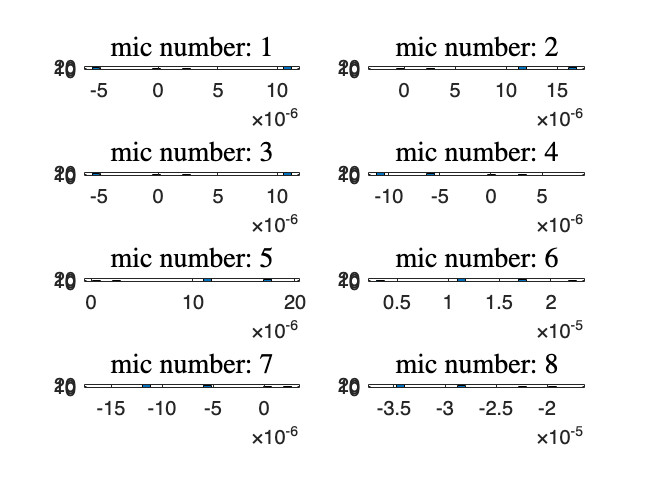

figure(1); clf;
for i = 1:size(y_toa,2)
    subplot(4,2,i);
    [N, l] = hist(meas_errors(:,i),20);
    Wb     = l(2)-l(1); % Bin widths
    Ny     = length(meas_errors(:,i)); % Nr of samples
    bar(l, N);
    title(['mic number: ',num2str(i)],'Interpreter','Latex','Fontsize',14)
end

## 2. Nonlinear least squares

load('experiment1.mat')
load('ground_truth1.mat')

### a) Nonlinear function $f$, and the noise covariance $\Sigma$

**Your text here** (*Please you the equation editor for equations)* **:**

### b) Jacobian

**Your text here** (*Please you the equation editor for equations)* **:**

### c) NLS algorithm

Implement the NLS algorithm to compute the position estimates **in the function templates** at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@f,"2a1"))

correct


disp(testmyresult(@Jacobian,"2a2"))

correct


### d) Computation of position estimates with NLS

Write your code in the box below, using the given initial state vector and maximum number of iterations.

% your code here
th0     = [0.12; 0.8; 70]; % initial state vector
maxiter = 137;             % maximum number of iterations

y_toa = y_toa - biases;
R = diag(vars);

[th_nls, P_nls] = NLS(y_toa, th0, R, maxiter, mic_locations);

### e) Visualisation and interpretation

Uncomment the code below.

**Your text here****:**

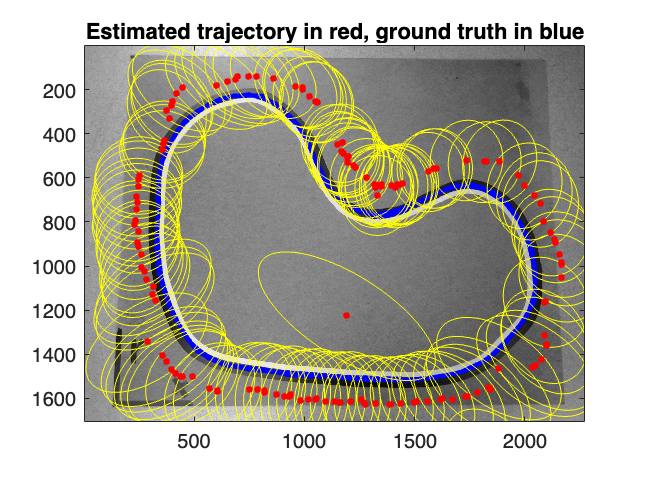

figure(2); clf;
plotresults(th_nls(1:2,:),P_nls(1:2,1:2,:),mic_locations',ground_truth);

## 3. Kalman filtering 

### a) KF algorithm

Implement the Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_kf,"3a1"))

correct


disp(testmyresult(@timeupdate_kf,"3a2"))

correct


### b) Computation of position estimates with KF

Write your code in the box below, using the given initial position and intial covariance matrix.

Tune $Q$ and $R_k$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

R = P_nls(1:2,1:2,:);
%Q = 0.3*mean(R(:,:,2:end),3);
Q = eye(2,2)*0.5*1e-6;
P_0 = eye(2,2)*10;
[p_kf,P_kf] = KF(th0(1:2), P_0, R, Q, th_nls((1:2),:));

### c) Visualisation

Plot the mean and covariance of the **filtered** distribution. Uncomment the plot below.

**Your text here:**

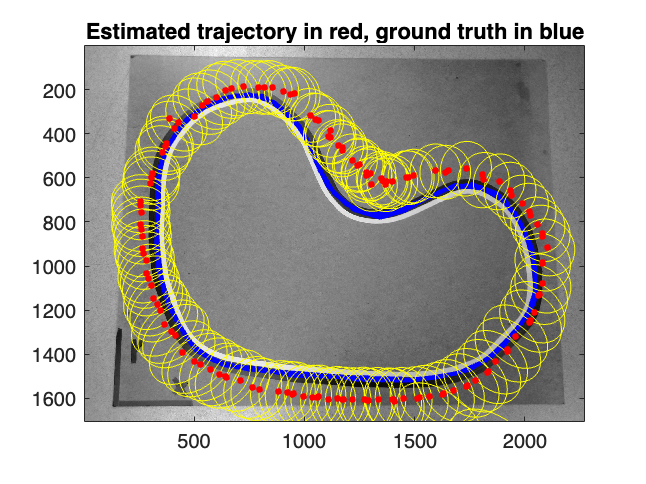

figure(3); clf;
plotresults(p_kf,P_kf,mic_locations',ground_truth);

## 4. Extended Kalman fitering

### a) EKF algorithm

Implement the extended Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check wheather your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_ekf,"4a1"))

correct


disp(testmyresult(@timeupdate_ekf,"4a2"))

correct


### b) Computation of position estimates with EKF

Tune $Q$ as explained in the exercise pdf and comment on your choices.

**Your text here:**

% Calculation of delta tau for use in timeupdate_ekf 
y_toa_later = y_toa(2:end,:);
y_toa_earlier = y_toa(1:end-1,:);
y_toa_diff = y_toa_later-y_toa_earlier;
delta_tau = mean(y_toa_diff, "all");
var_tau = var(y_toa_diff);

R = diag(vars);
Q = diag([0.5*1e-6, 0.5*1e-6, mean(var_tau)]);
P_0 = eye(3,3)*10;
[th_ekf,P_ekf] = EKF(th0, P_0, y_toa, mic_locations, R, Q);


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution.

**Your text here:**

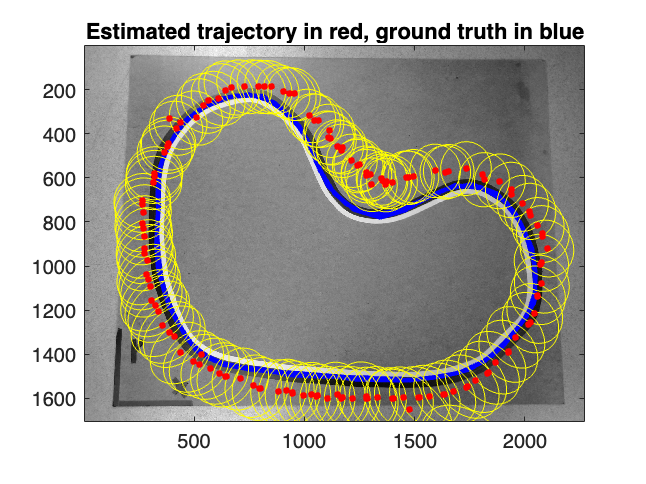

figure(4); clf;
plotresults(th_ekf(1:2,:),P_ekf(1:2,1:2,:),mic_locations',ground_truth);

# Copy all your functions below this text before exporting to PDF!! 

## Functions

NLS

function ftheta = f(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % ftheta            evaluation of f at current state estimate
    
    c      = 343; % in [m/s]
    for mic = 1:length(mic_locations)
        ftheta(mic) = theta(3) + (1/c)*norm(theta(1:2) - mic_locations(mic, :)');
    end
    ftheta = ftheta';
end

function dF = Jacobian(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % dF                evaluation of Jacobian at current state estimate
    
    c = 343; % in [m/s]

    dF = zeros(8,3);
    for mic = [1:8]
        denom = c*norm(theta(1:2)-mic_locations(mic,:)');
        x_diff = theta(1) - mic_locations(mic, 1)';
        y_diff = theta(2) - mic_locations(mic, 2)';
        dF(mic,:) = [x_diff/denom, y_diff/denom, 1];
    end

end

function [th_hat, P_hat] = NLS(yk,th_hat0,R,maxiter,mic_locations)
    % INPUT: 
    % y_k               kth measurement
    % th_hat0           initial estimate
    % R                 covariance matrix of measurement noise
    % maxiter           maximum number of iterations 
    % mic_locations     microphone locations
    
    % OUTPUT    
    % th_hat            mean of kth NLS estimate
    % P_hat             covariance matrix of kth NLS estimate
    
    W = inv(R);
    th_hat(:,1) = th_hat0;
    P_hat(:,:,1) = 10*eye(3,3);

    for iter = [2:maxiter]
        F = Jacobian(th_hat(:,iter-1), mic_locations);
        ftheta = f(th_hat(:,iter-1), mic_locations);
        err = yk(iter-1,:)' - ftheta;

        delta_theta = inv(F'*W*F)*F'*W*err;
        th_hat(:,iter) = th_hat(:,iter-1) + delta_theta;
        P_hat(:,:,iter) = inv(F'*W*F);    
    end

end

KF

function [p_kk,P_kk] = timeupdate_kf(p_k,P_k,Q)
    % INPUT
    % p_k   mean of filtering distribution for k|k
    % P_k   covariance matrix of filtering distribution for k|k
    % Q     process noise covariance matrix
    % OUTPUT
    % p_kk  mean of predictive distribution for k+1|k
    % P_kk  covariance of predictive distribution for k+1|k
    
    p_kk = p_k;
    P_kk = P_k + Q;

end

function [p_kf,P_kf] = measupdate_kf(p_k,P_k,R_k,y_k)
    % INPUT
    % p_k   mean of predictive distribution for k|k-1
    % P_k   covariance of predictive distribution for k|k-1
    % R_k   kth measurement noise covariance matrix
    % y_k   kth measurment
    % OUTPUT
    % p_kf  mean of filtering distribution for k|k
    % P_kf  covariance matrix of filtering distribution for k|k

    K_k = P_k*inv(P_k + R_k);
    p_kf = p_k + K_k*(y_k - p_k);
    P_kf = P_k - P_k*inv(P_k + R_k)*P_k;

end

function [p_kf,P_kf] = KF(p_0,P_0,R,Q,y)
    % INPUT: 
    % p_0       prior mean
    % P_0       prior covariance matrix
    % R         Measurement noise covariance matrices for k = 1,...,137
    % Q         Process noise covariance matrix
    % y         Measurements for k = 1,...,137
    % OUTPUT    
    % p_kf      Mean of the filtered distribution for every k
    % P_kf      Covariance matrix of the filtered distribution for every k
    
    p_kf(:,1) = p_0;
    P_kf(:,:,1) = P_0;

    for iter = [2:137]
        y_k = y(:,iter);
        R_k = R(:,:,iter);
        [p_kk,P_kk] = timeupdate_kf(p_kf(:, iter-1), P_kf(:,:,iter-1), Q);
        [p_kf(:,iter),P_kf(:,:,iter)] = measupdate_kf(p_kk,P_kk,R_k,y_k);
    end

end

EKF

function [th_kk,P_kk] = timeupdate_ekf(th_k,P_k,Q)
    % INPUT
    % th_k   mean of filtering distribution for k|k
    % P_k    covariance matrix of filtering distribution for k|k
    % Q      process noise covariance matrix
    % OUTPUT
    % th_kk  mean of predictive distribution for k+1|k
    % P_kk   covariance of predicted distribution for k+1|k
    
    th_kk(1:2,1) = th_k(1:2,1);
    th_kk(3,1) = th_k(3,1) + 0.5115;
    P_kk = P_k + Q;

end

function [th_ekf,P_ekf] = measupdate_ekf(th_k,P_k,y_k,mic_locations,R)
    % INPUT
    % th_k              mean of predictive distribution for k|k-1
    % P_k               covariance of predictive distribution for k|k-1
    % y_k               kth measurment
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % OUTPUT
    % th_ekf            mean of filtering distribution for k|k
    % p_ekf             covariance matrix of filtering distribution for k|k

    H_k = Jacobian(th_k, mic_locations);
    h_k = f(th_k, mic_locations);
    K_k = P_k*H_k'*inv(H_k*P_k*H_k' + R);
    th_ekf1 = th_k;
    th_ekf2 = K_k*(y_k - h_k);
    th_ekf = th_ekf1 + th_ekf2;
    P_ekf = P_k - K_k*H_k*P_k;
end

function [th_ekf,P_ekf] = EKF(th_0,P_0,y,mic_locations,R,Q)
    % INPUT 
    % th_0              prior mean
    % P_0               prior covariance matrix
    % y                 measurements for k = 1,...,137
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % Q                 process noise covariance matrix
        
    % OUTPUT    
    % th_ekf            mean of the filtering distribution for every k
    % P_ekf             covariance matrix of the filtering distribution for every k    
        
    th_ekf(:,1) = th_0;
    P_ekf(:,:,1) = P_0;

    for iter = [2:137]
        y_k = y(iter,:)';
        [th_kk,P_kk] = timeupdate_ekf(th_ekf(:, iter-1), P_ekf(:,:,iter-1), Q);
        [th_ekf(:,iter),P_ekf(:,:,iter)] = measupdate_ekf(th_kk,P_kk,y_k,mic_locations,R);
    end
end